clc;
clear;
close all;

L(1)=Link([0 8 0 0],'modified');
L(2)=Link([0 0 -3 pi/2],'modified');
L(3)=Link([0 0 15 0],'modified');
L(4)=Link([0 12 1 pi/2],'modified');
L(5)=Link([0 0 0 pi/2],'modified');
robot=SerialLink(L,'name','Brazo')

 
robot = 
 
Brazo:: 5 axis, RRRRR, modDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          8|          0|          0|          0|
|  2|         q2|          0|         -3|     1.5708|          0|
|  3|         q3|          0|         15|          0|          0|
|  4|         q4|         12|          1|     1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


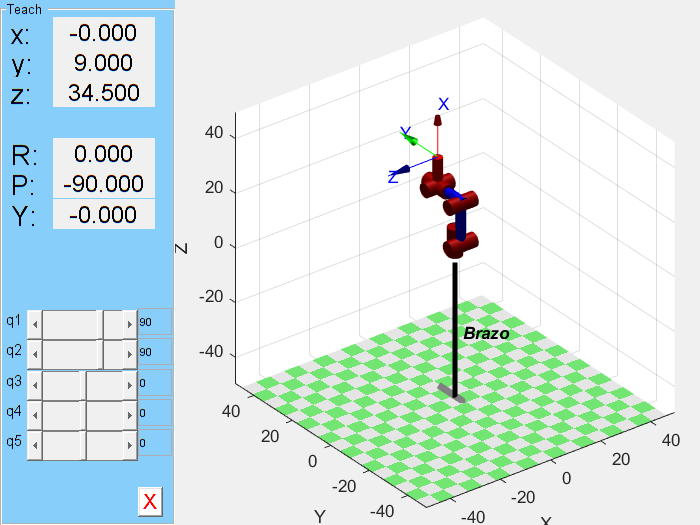

robot.tool=transl(10.5,0,0);
robot.teach([pi/2 pi/2 0 0 0 ])

clc;
clear;
syms L0 L1 L2 L3 L4 L5 q1 q2 q3 q4 q5 real
sympref('FloatingPointOutput',false);

dh=[0 0 L0 q1;pi/2 -L1 0 q2;0 L2 0 q3-pi/2;pi/2 L3 L4 q4-pi/2;pi/2 0 0 q5];

## Denavit-Hartemberg table

        
$$\alpha_{i-1}$$
 
$$a_{i-1}$$
   
$$d_i$$
    
$$\phi_i$$


disp(dh)

$$\left(\begin{array}{cccc} 0 & 0 & L_{0} & q_{1}\\ \frac{\pi }{2} & -L_{1} & 0 & q_{2}\\ 0 & L_{2} & 0 & q_{3}-\frac{\pi }{2}\\ \frac{\pi }{2} & L_{3} & L_{4} & q_{4}-\frac{\pi }{2}\\ \frac{\pi }{2} & 0 & 0 & q_{5} \end{array}\right)$$

for i=1:5
   frame{i}=[cos(dh(i,4)) -sin(dh(i,4)) 0 dh(i,2)
    sin(dh(i,4))*cos(dh(i,1)) cos(dh(i,4))*cos(dh(i,1)) -sin(dh(i,1)) -dh(i,3)*sin(dh(i,1))
    sin(dh(i,4))*sin(dh(i,1)) cos(dh(i,4))*sin(dh(i,1)) cos(dh(i,1)) dh(i,3)*cos(dh(i,1))
    0 0 0 1];   
end
frame{6}=sym(transl(L5,0,0));
for i=1:6
    fprintf('frame %d with respect to %d ',i,i-1)
    disp(frame{i})
end

frame 1 with respect to 0 

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame 2 with respect to 1 

$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & -L_{1}\\ 0 & 0 & -1 & 0\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame 3 with respect to 2 

$$\left(\begin{array}{cccc} \cos\left(q_{3}-\frac{\pi }{2}\right) & -\sin\left(q_{3}-\frac{\pi }{2}\right) & 0 & L_{2}\\ \sin\left(q_{3}-\frac{\pi }{2}\right) & \cos\left(q_{3}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame 4 with respect to 3 

$$\left(\begin{array}{cccc} \cos\left(q_{4}-\frac{\pi }{2}\right) & -\sin\left(q_{4}-\frac{\pi }{2}\right) & 0 & L_{3}\\ 0 & 0 & -1 & -L_{4}\\ \sin\left(q_{4}-\frac{\pi }{2}\right) & \cos\left(q_{4}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame 5 with respect to 4 

$$\left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

frame 6 with respect to 5 

$$\left(\begin{array}{cccc} 1 & 0 & 0 & L_{5}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

sympref('FloatingPointOutput',true);
fkinematics=simplify(frame{1}*frame{2}*frame{3}*frame{4}*frame{5}*frame{6})

fkinematics=simplify(subs(fkinematics,{L0 L1 L2 L3 L4 L5},{8,3,15,1,12,9}))

**Jacobian**

q={q1 q2 q3 q4 q5};
p=fkinematics(1:3,end);
for i=1:3
    for j=1:5
        Jtool(i,j)=simplify(diff(p(i),q{j}));
    end
end
disp(Jtool)

RrelT=tr2rt(fkinematics)';
J=simplify(RrelT*Jtool);
disp(simplify(J))